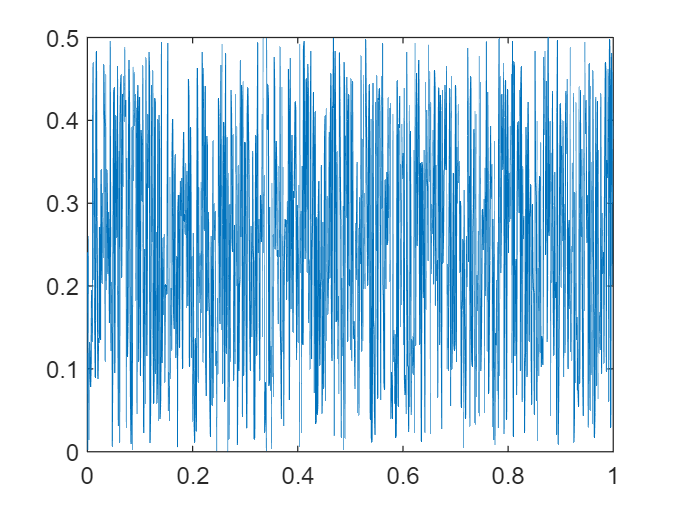

clear
fs=1000;
dt=1/fs;
t=0:dt:1;
f1=rand(1,length(t)).*0.5;
plot(t,f1);

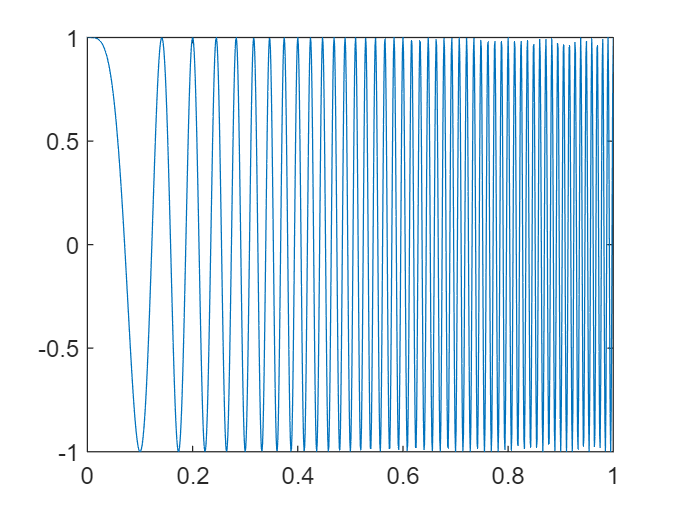

f2=chirp(t,0,1);
plot(t,f2);

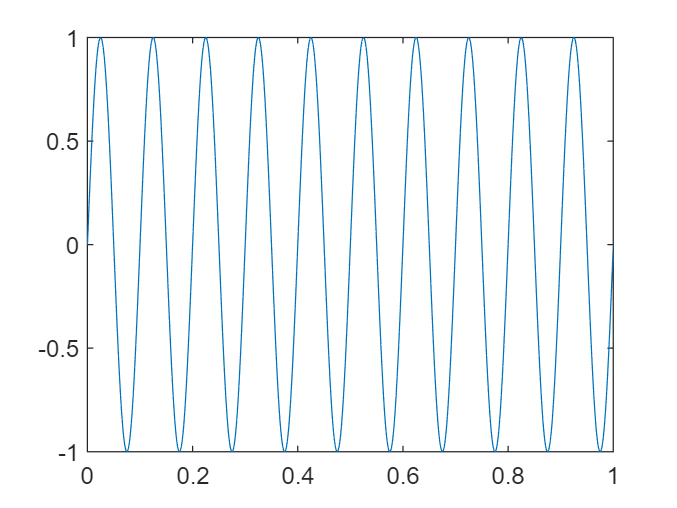

f3=sin(2*pi*10*t);
plot(t,f3);

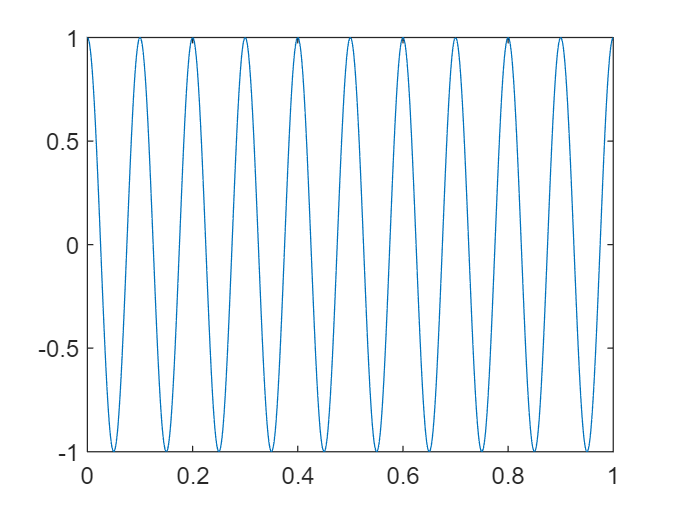

f4=cos(2*pi*10*t);
plot(t,f4);

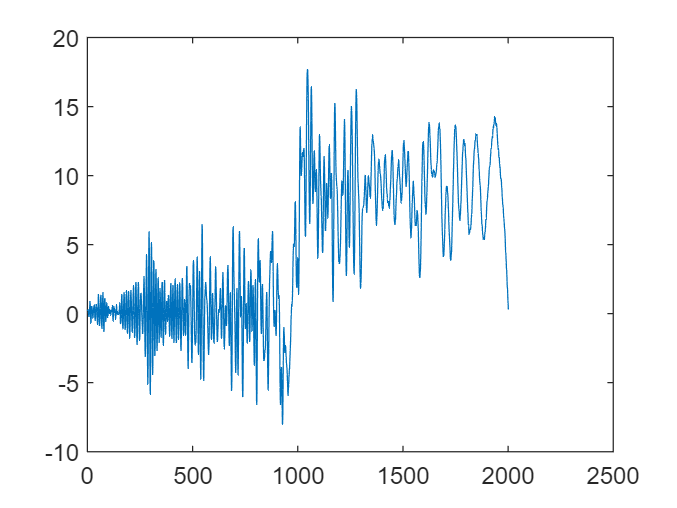


f12=xcorr(f1,f2);
plot(f12);

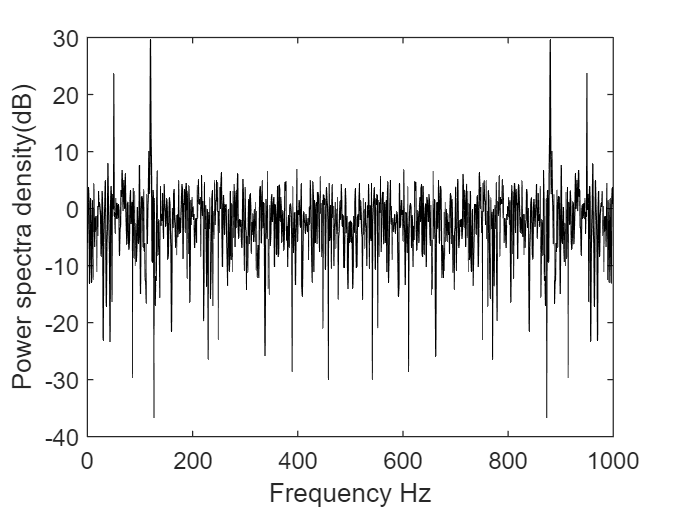

 
clear
fs=1000;
dt=1/fs;
t=0:dt:1;
fI=sin(2*pi*50*t)+2*sin(2*pi*120*t)+randn(size(t));

Pxx=abs(fft(f1)).^2/1001;
N=length(f1); df=fs/N; f=df*(0:N-1);
plot(f,10*log10(Pxx),'black')
xlabel('Frequency Hz'), ylabel('Power spectra density(dB)')


var(fft(f1))

ans = 3.3211e+03

var(fft(f1(1:500)))

ans = 1.6130e+03

var(fft(f1(1:250)))

ans = 744.0957

The longer the signal the higher the variance

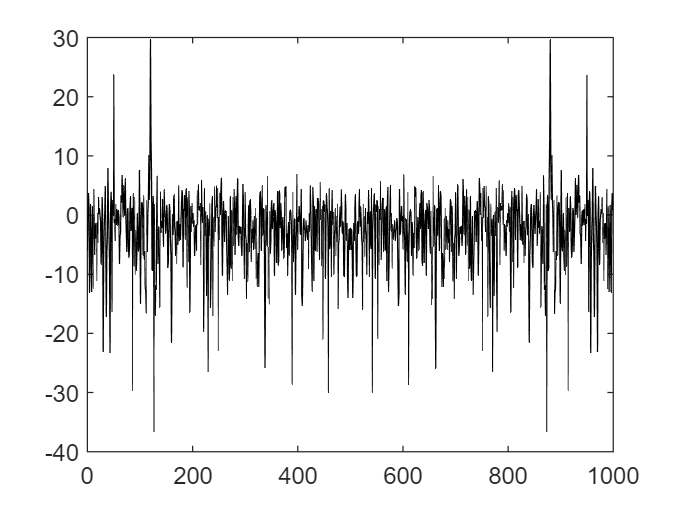

pxx=pwelch(f1,250);
plot(f,10*log10(Pxx),'black')